l_axes = 2.588; % Total length = 4.084 m
l_front = 0.839;
l_rear = 0.657;
b_width = 1.771/2;

xpos = 0;
ypos = 0;
theta = 0;

Ax = xpos + (l_axes+l_front).*cos(theta) - b_width.*sin(theta);
Ay = ypos + (l_axes+l_front).*sin(theta) + b_width.*cos(theta);

Bx = xpos + (l_axes+l_front).*cos(theta) + b_width.*sin(theta);
By = ypos + (l_axes+l_front).*sin(theta) - b_width.*cos(theta);

Cx = xpos - l_rear.*cos(theta) + b_width.*sin(theta);
Cy = ypos - l_rear.*sin(theta) - b_width.*cos(theta);

Dx = xpos - l_rear.*cos(theta) - b_width.*sin(theta);
Dy = ypos - l_rear.*sin(theta) + b_width.*cos(theta);

# Circles [x0, y0, rad]

radius = b_width + 0.15

radius = 1.0355

dx = (l_rear + l_axes + l_front)/2 - l_rear;
circ(1,:) = [0.5+dx, 0, radius];
circ(2,:) = [1.5+dx, 0, radius];
circ(3,:) = [-0.5+dx, 0, radius];
circ(4,:) = [-1.5+dx, 0, radius];

%% Rectangles [x0, y0, a, b, psi]
rect(1,:) = [0, 0, 4.084, 1.771, 0];

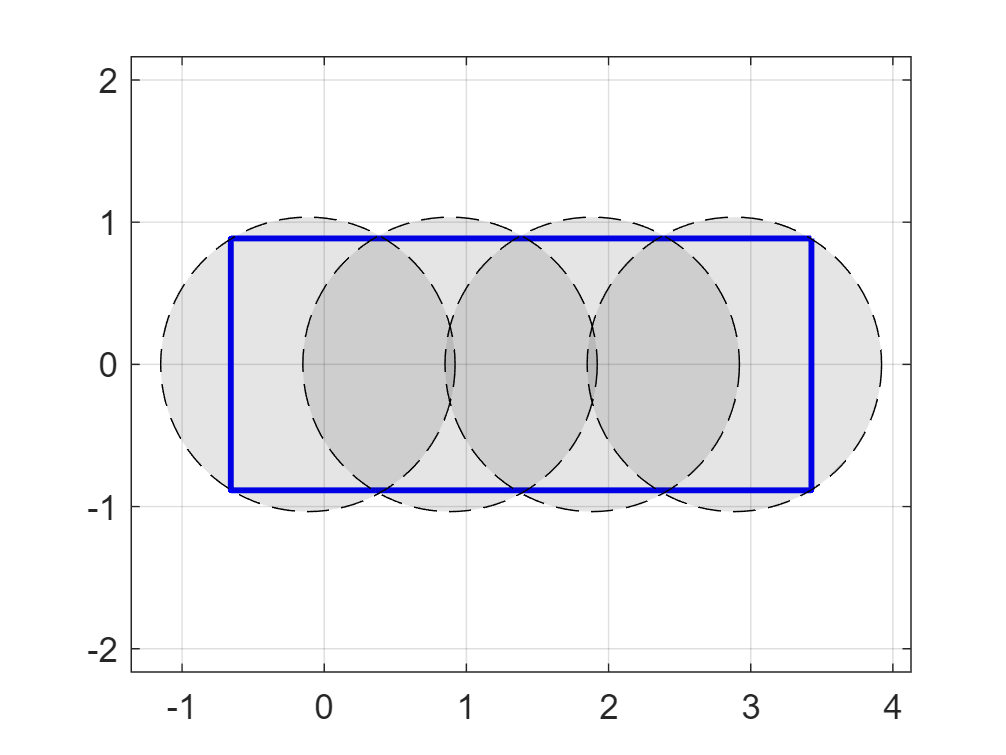


figure;
plot([Ax Bx Cx Dx Ax], [Ay By Cy Dy Ay], 'b-',"LineWidth",2); hold on;
drawCircle(circ);
% drawRect(rect);

grid on; axis equal;
hold off;

point = (-1.5:1:1.5) + (l_rear + l_axes + l_front)/2 - l_rear

point =    -0.1150    0.8850    1.8850    2.8850


my_array = [80.6, 120.8, -115.6, -76.1, 131.3, 105.1, 138.4, -81.3, -95.3, 89.2, -154.1, 121.4, -85.1, 96.8, 68.2];
temp = my_array(1:end-1).*my_array(2:end);
sum(temp < 0)

ans = 8